# Figure 3b - Consistency of our data with deVeld

There will also be a panel showing how well we fit a weighted sum of the data from our four subjects onto the deVeld subject.

ieInit;
waves = 500:5:700;
symbols = {'kx-','k*-','k^-','ko-'};

T = oeDatabaseCreate;

tongue = ieReadSpectra('TongueVeld2003.mat',wave);
ieNewGraphWin;
%plot(wave,tongue/max(tongue(:)),'k--','lineWidth',2); hold on;
plot(wave,tongue/tongue(1),'k--','lineWidth',2); hold on;

## Subject 1 (Z) excitation light 405 

Read in the files at all excitation levels

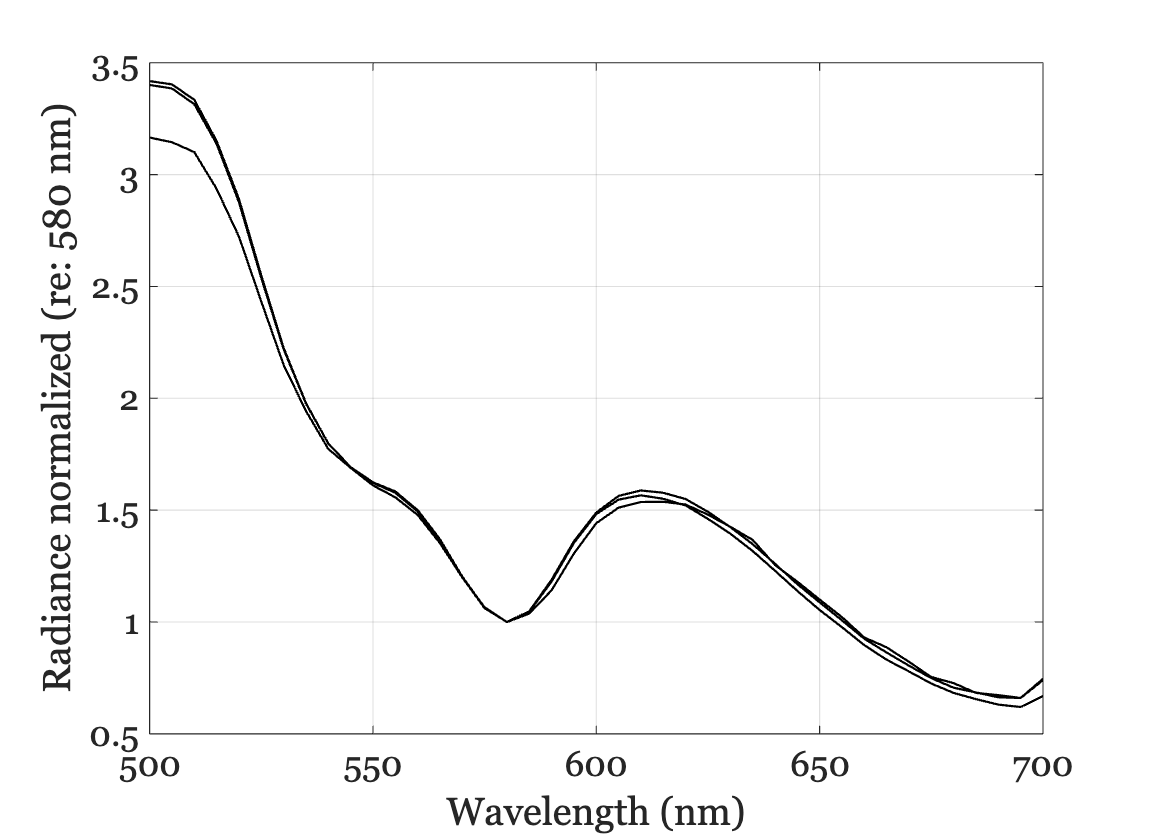

eWave = 405;
[files405,tRows405] = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data405,'k-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) excitation light 415 

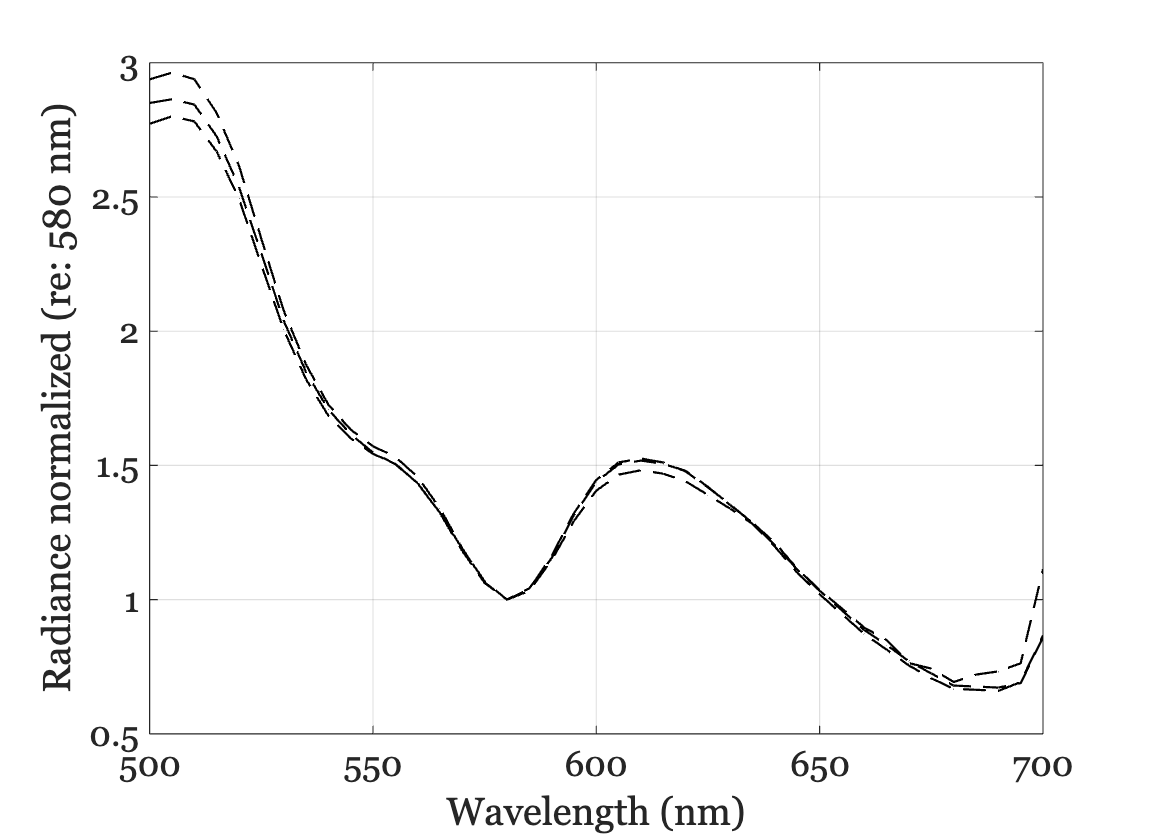

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data415 = oeReadFiles(files415,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data415,'k--');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Subject 1 (Z) Lip excitation light 450

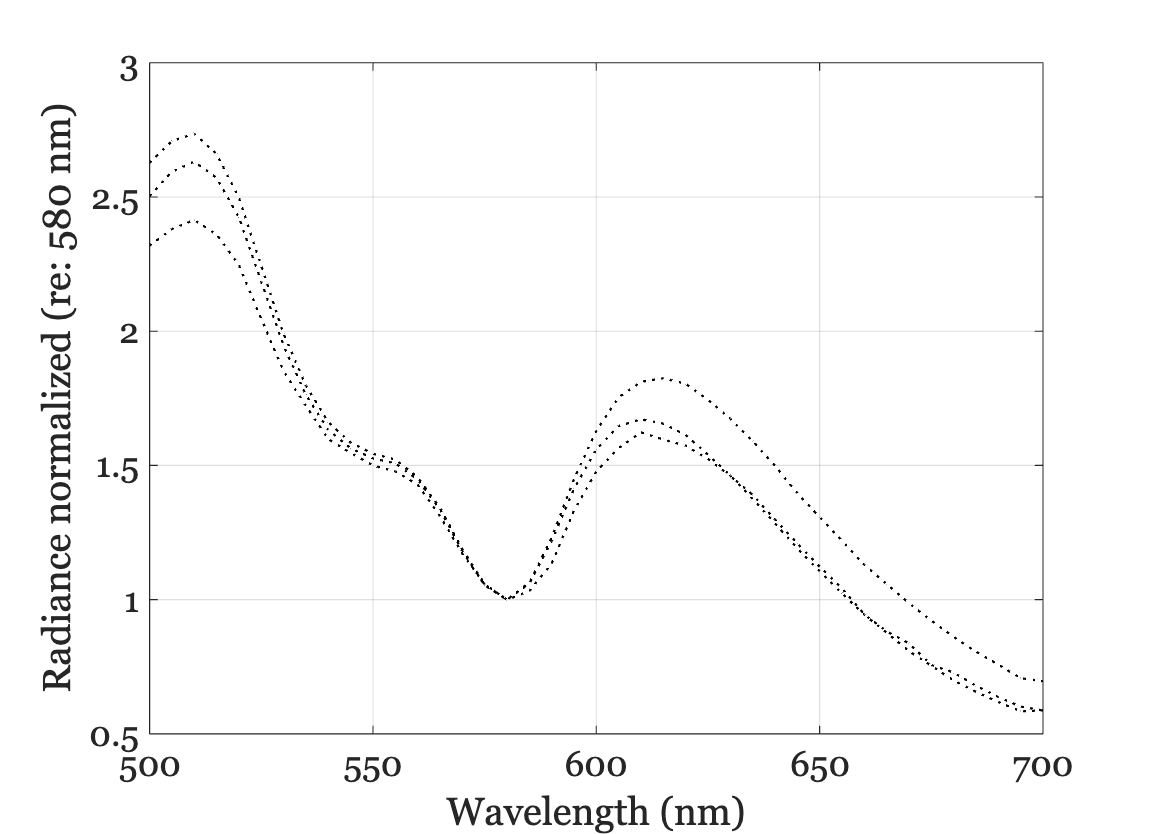

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','lip', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data450 = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data450,'k:');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;

## Pooled lip 

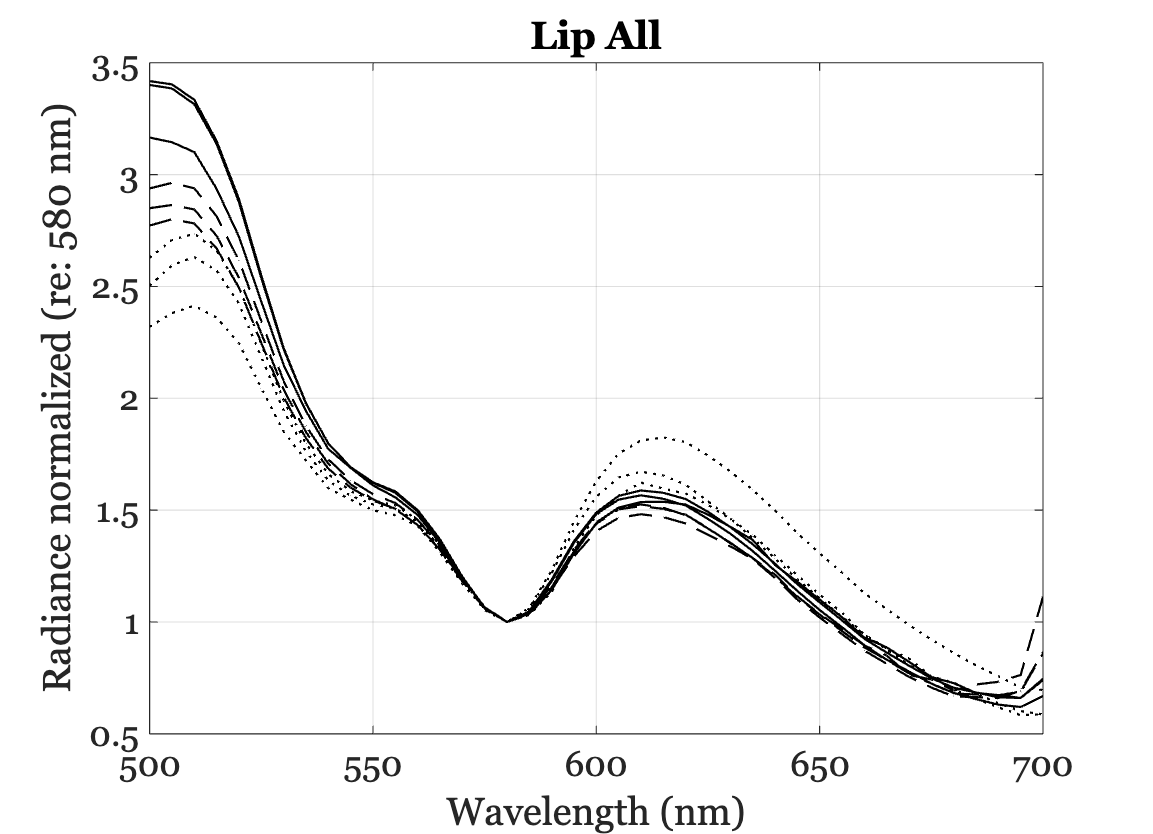

plot(waves,data405,'k-'); hold on;
plot(waves,data415,'k--'); hold on;
plot(waves,data450,'k:'); hold on;

xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Lip All')

## Tongue 405 

Read in the files at all excitation levels

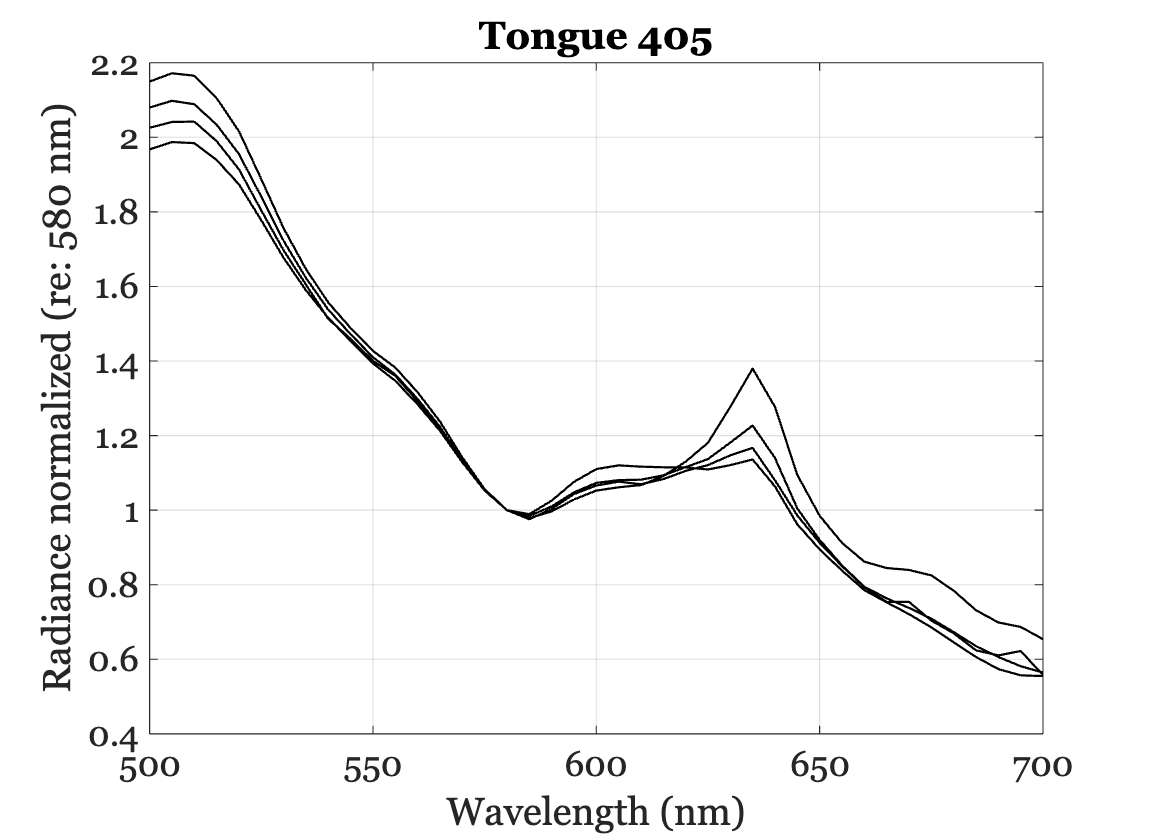

eWave = 405;
files405 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data405,'k-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 405');

## Tongue 415

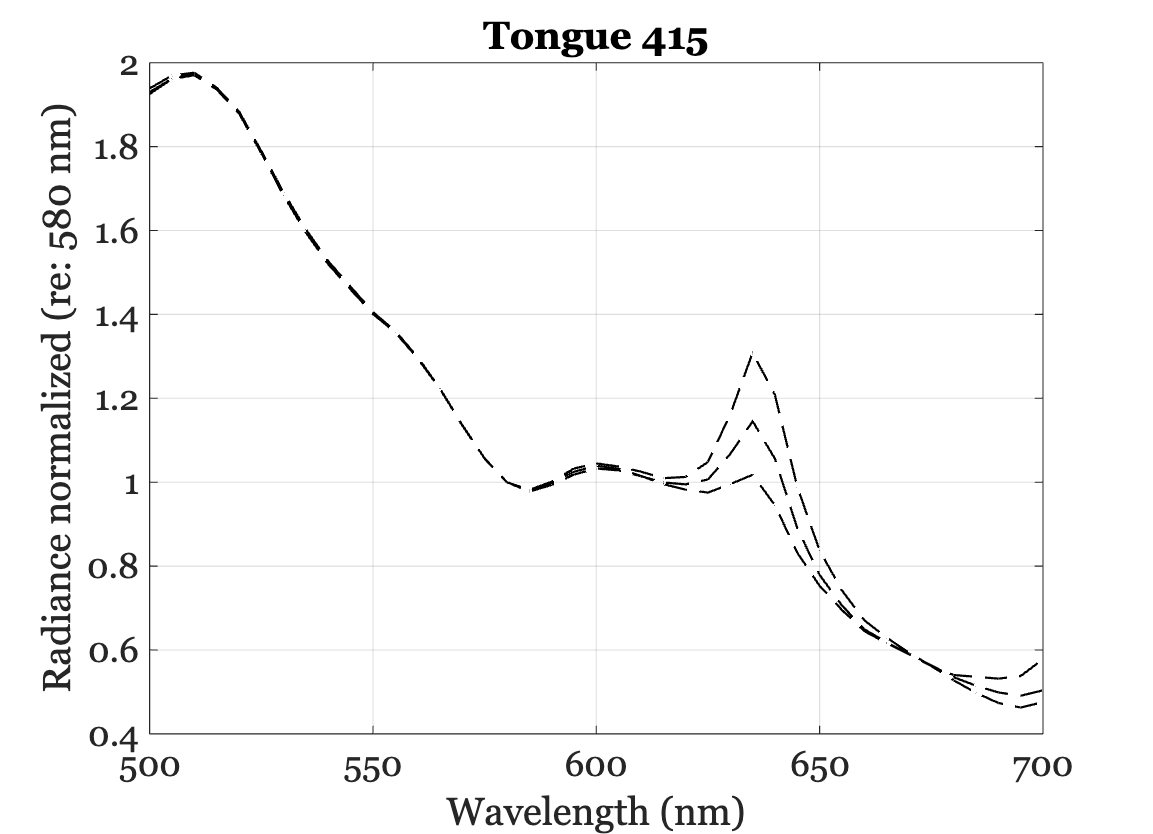

eWave = 415;
files415 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data415 = oeReadFiles(files415,'waves',waves,'normalized wave',580);
ieFigure;
plot(waves,data415,'k--');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 415');

## Tongue  450

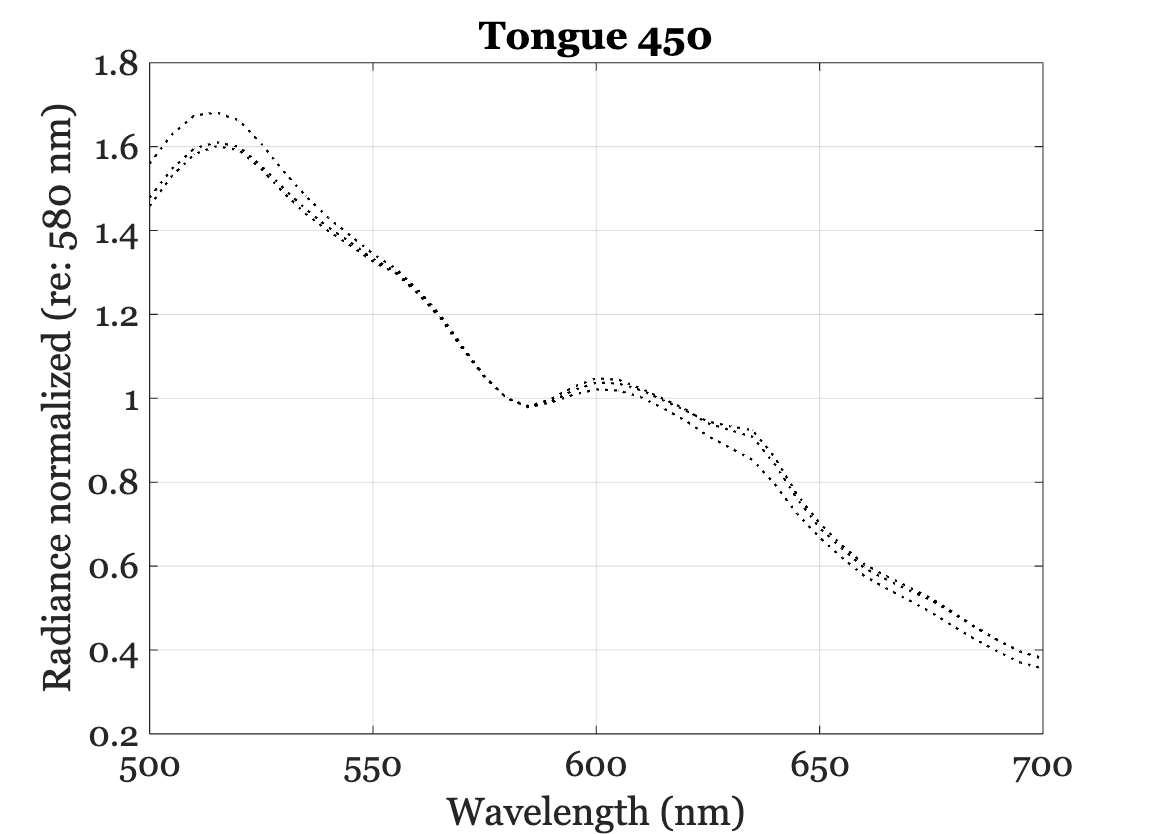

eWave = 450;
files450 = ieTableGet(T,'subject',theSubject,...
    'substrate','tongue', ...
    'ewave',eWave, ...
    'date','2024-03-14');

data = oeReadFiles(files450,'waves',waves,'normalized wave',580);

ieFigure;
plot(waves,data,'k:');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on;
title('Tongue 450');

## Pooled tongue

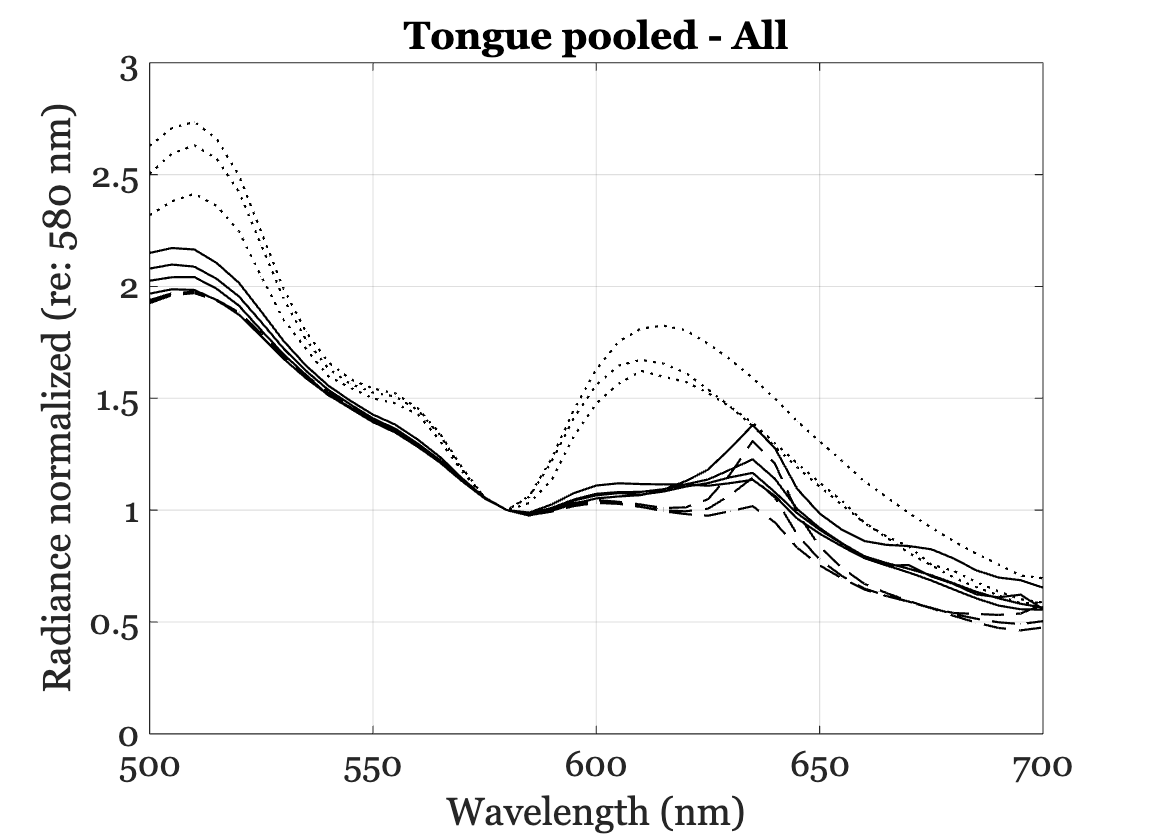

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(waves,data415,'k--');
plot(waves,data450,'k:');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; title('Tongue pooled - All')